# Série de Fourier

## Boas práticas

%% Limpa as variáveis, fecha as figuras, limpa a tela
%% Define variáveis globais

disp('Executando o bloco 0...');

Executando o bloco 0...



clear; %% Limpa as variáveis
close all; %% Fecha as figuras
clc; %% Limpa a tela


%% Definição das variáveis estáticas iniciais

T0 = 1; % Período fundamental

w0 = (2*pi)/T0; % Frequência fundamental

N = 20; % Número de termos que compõem a série de Fourier

n = 0; % Variável de incremento no cálculo dos termos que compõem a análise de Fourier

K = 30 % Número de pontos de 'sampling' da função

K = 30


i = 0 % Incremento universal para uso em um 'for'

i = 0


k = 0 % Incremento universal para uso em um 'for'

k = 0


Xn = [] % Amplitudes da análise discreta de Fourier


Xn =

     []




soma = 0 % Valor a ser armazenada a soma na Síntese discreta de Fourier

soma = 0


gk = [] % Valores assumidos pela função g(t) na posição k * T


gk =

     []





%% Definição das variáveis simbólicas iniciais

syms t % Tempo contínuo

syms Dn % Amplitudes da análise de Fourier

Dn = [];

syms Sintese % Função de t resultante da síntese de Fourier

Sintese = @(t) 0;


## Definição dos sinais periódicos

%% Define a função g(t) a ser otimizada, plota a função g(t)

disp('Executando o bloco 1...');

Executando o bloco 1...


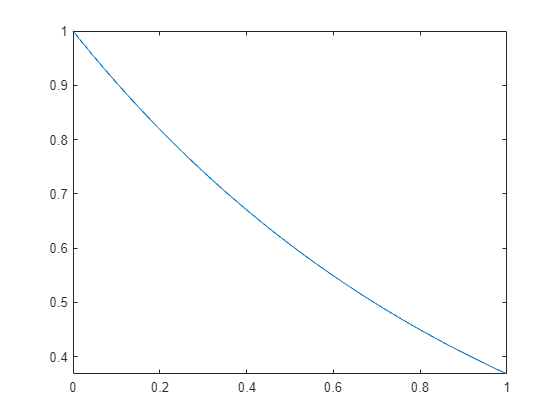

g = @(t) exp(-t); %% Definição da função g(t)

figure(1);

fplot(g(t),[0 1]); %% Plot da função simbólica g(t), de t = 0 até t = 1

## Análise de Fourier

%% Definição dos coeficientes Dn (forma exponencial da série de Fourier)

disp("Executando o bloco 2...")

Executando o bloco 2...



%% Cálcula as amplitudes da análise de Fourier para cada n e armazena no array Dn na posição n + 1
for n = -N: N
Dn(n + N + 1) = (1/T0)*int(g(t)*exp(j*n*w0*t), 0, T0);
end


## Síntese de Fourier

disp("Executand o bloco 3...")

Executand o bloco 3...


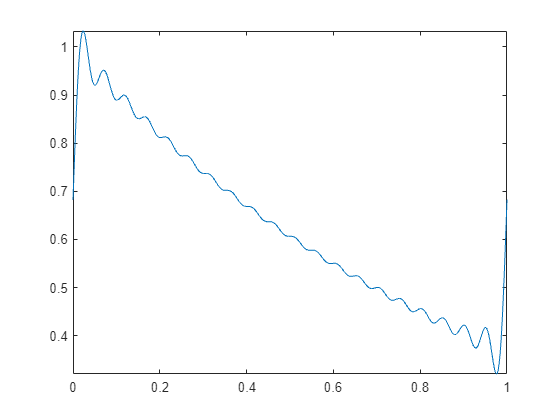


%% Com base nas amplitudes obtidas na análise de Fourier, somas os termos exponenciais de amplitudes Dn(n) no termo Soma

for n = -N : N

Sintese = Sintese + Dn(n + N + 1)*exp(-j*n*w0*t);

end

%% Plota a função Sintese em relação ao tempo em um período determinado

fplot(Sintese, [0 1]);

## Série Discreta de Fourier

disp("Executand o bloco 4...")

Executand o bloco 4...


%% Armazena valores de discretos da função g(t) no array g(k)

for i = 0: K - 1

    gk(i+1) = g((T0)/K*i);

end


## Síntese discreta de Fourier

%% Calcula, por somatória, as amplitudes Xn que irão compor a série de Fourier discreta

for i = -N: N

for k = 0: N - 1

soma = soma + gk(k+1)*exp(-j*(2*pi/N)*i*k); % Calcula o somatório da fórmula para cada Xn

end

Xn(i+N+1) = (1/N)*soma; % Atrubui o valor calculado para cada Xn

soma = 0;

end


## Análise discreta de Fourier

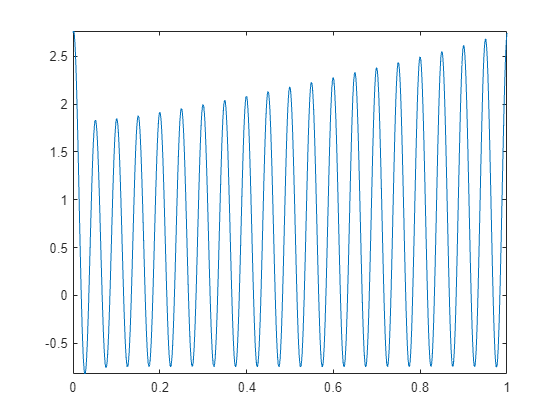

%% Com base nas amplitudes obtidas na análise de Fourier, somas os termos exponenciais de amplitudes Dn(n) no termo Soma

Sintese = 0;

for n = -N : N

Sintese = Sintese + Xn(n + N + 1)*exp(-j*n*w0*t);

end

%% Plota a função Sintese em relação ao tempo em um período determinado

fplot(Sintese, [0 1]);

## Avaliação de desempenho de algoritmos discretos